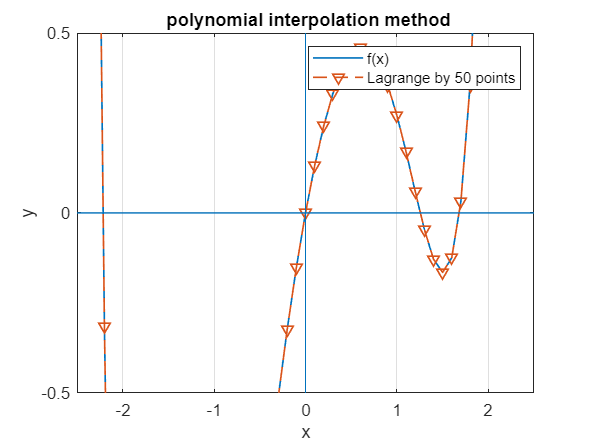

%part a
f = @(x) (0.11 * x.^6 - 0.01 * x.^5 - 0.233 * x.^4 - 0.01 * x.^3 - x.^2 + sqrt(2) * x );
fx = [-2.5:.1:2.5];
y = f(fx);



f1 = @(x) (0.11 * x.^6 - 0.01 * x.^5 - 0.233 * x.^4 - 0.01 * x.^3 - x.^2 + sqrt(2) * x );
datx = [-2.5:.1:2.5];
daty = f1(datx);
count = 0;
LLY = 0;
LLY = NaN(1,length(fx));
for i = -2.5 : .1 : 2.5
    count = count + 1;
    LLY(count) = Lagrange(datx, daty, i);
end

plot(fx,y,fx, LLY,'--v','LineWidth', 1);
xL = xlim;
yL = ylim;
line([0 0], yL);  %x-axis
line(xL, [0 0]);  %y-axis
title(' polynomial interpolation method');
legend('f(x)','Lagrange by 50 points');
xlabel('x');
ylabel('y');
%part b
grid on;
ylim([-0.5 0.5]) %to check the roots closer
xlim([-2.5 2.5])


%part c
tol = 1 * 10^(-5);
root1_sm = secant_method(f,-2.5, -2,tol,10);

  -2.215710958164682

     5



root2_sm = secant_method(f,-0.25,0.25,tol,10);

    -5.681065594040333e-10

     4



root3_sm = secant_method(f,0.5, 1.5,tol,10);

   1.255662545560641

     4



root4_sm = secant_method(f,1.5, 2,tol,10);

   1.685278714974606

     9



%part d
tol = 1 * 10^(-5);
df =@(x) ((0.01 * x.^5 + 0.233 * x.^4 + 0.01 * x.^3 + x.^2 - (2^(1/2)) * x) / 0.11)^(1/6);

root1_fpi = fixed_point_iteration(df,-2.5,tol)

x =   -2.500000000000000


   1.685279152430591



root1_fpi =    1.685279152430591


root2_fpi = fixed_point_iteration(df,-0.5,tol)

x =   -0.500000000000000


   1.685278187327265



root2_fpi =    1.685278187327265


root3_fpi = fixed_point_iteration(df,0.75,tol)

x =    0.750000000000000


  1.685278916059855 + 0.000000448705602i



root3_fpi =   1.685278916059855 + 0.000000448705602i


root4_fpi = fixed_point_iteration(df,2,tol)

x =      2


   1.685279171356685



root4_fpi =    1.685279171356685


disp('----------')

----------


fp1 = ["x0 = -2.5 converge at point ", root1_fpi];
fp2 = ["x0 = -0.5 converge at point ",root2_fpi];
fp3 = ["x0 = 0.75 converge at point ",root3_fpi];
fp4 = ["x0 = 2 converge at point ",root4_fpi];
disp(fp1);

    "x0 = -2.5 converge at point "    "1.6853"



disp(fp2);

    "x0 = -0.5 converge at point "    "1.6853"



disp(fp3);

    "x0 = 0.75 converge at point "    "1.6853+4.4871e-07i"



disp(fp4);

    "x0 = 2 converge at point "    "1.6853"

